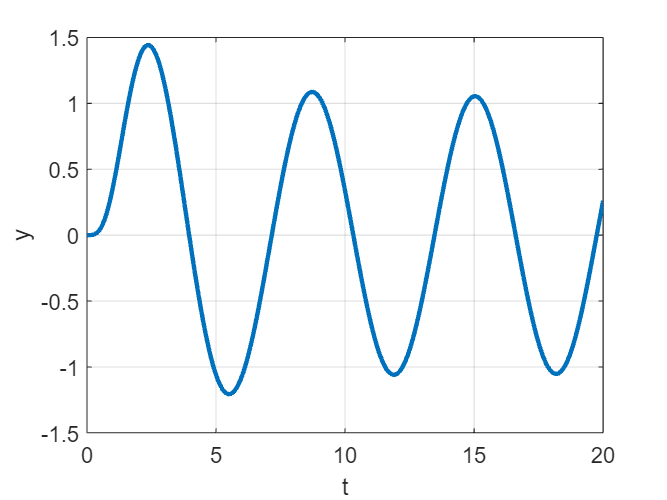

%% 初始设置
close all,clear,clc,
tic,
% 初始化仿真时间区间
t0 = 0.0;
tf = 20.0;

%初始条件求解
A = [
    3 -1 0 0 0;
    0 3 -1 0 0;
    0 0 3 -1 0;
    0 0 0 3 -1;
    16 24 18 6 1
    ];
B = [0;0;0;0;5*exp(0)+6*sin(pi/3)];
X0 = inv(A)*B;
x10 = X0(1);
x20 = X0(2);
x30 = X0(3);
x40 = X0(4);
%% 仿真
state0 = [x10;x20;x30;x40]; %状态向量初值

[tout,stateout] = ode45(@statequation02, [t0, tf], state0);

%输出t0-tf每一时刻的状态
x1out = stateout(:, 1);
x2out = stateout(:, 2);
x3out = stateout(:, 3);
x4out = stateout(:, 4);
yout = 3*x1out - x2out;

%画图
figure;
plot(tout, yout, 'LineWidth', 2);
ylabel('y');
xlabel('t');
grid on;


toc

历时 0.143281 秒。


function statedot=statequation02(t,state)
% 函数
% x = [y,y',y'',y''']
x1 = state(1);
x2 = state(2);
x3 = state(3);
x4 = state(4);

%状态方程
u = 5*exp(-0.5*t)*cos(t) + 6*sin(t+pi/3);
%du = -( 5*0.5*exp(-0.5*t)*cos(t) + 5*exp(-0.5*t)*sin(t) ) + 6*cos(t+pi/3);
x1dot = x2;
x2dot = x3;
x3dot = x4;
x4dot = -6*x4 - 18*x3 - 24*x2 - 16*x1 + u;%3*u - du;

%输出得到的四个状态量
statedot=[x1dot;x2dot;x3dot;x4dot];
end